# State-space system of 4-area model

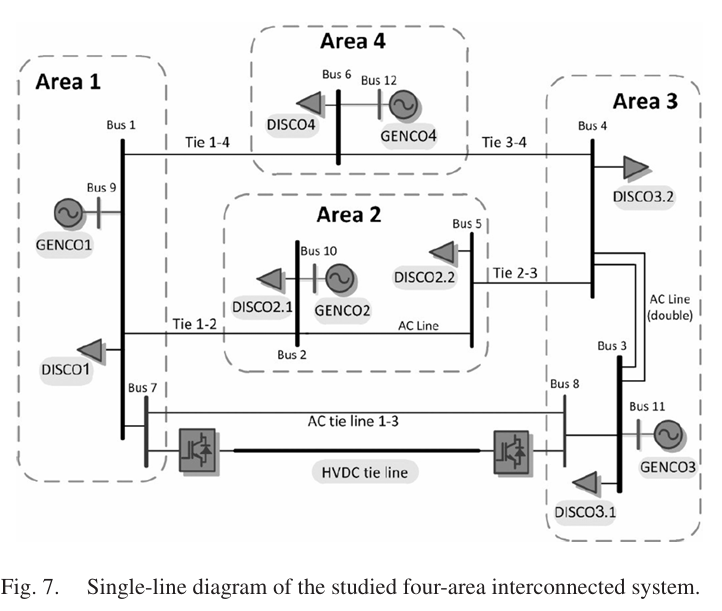

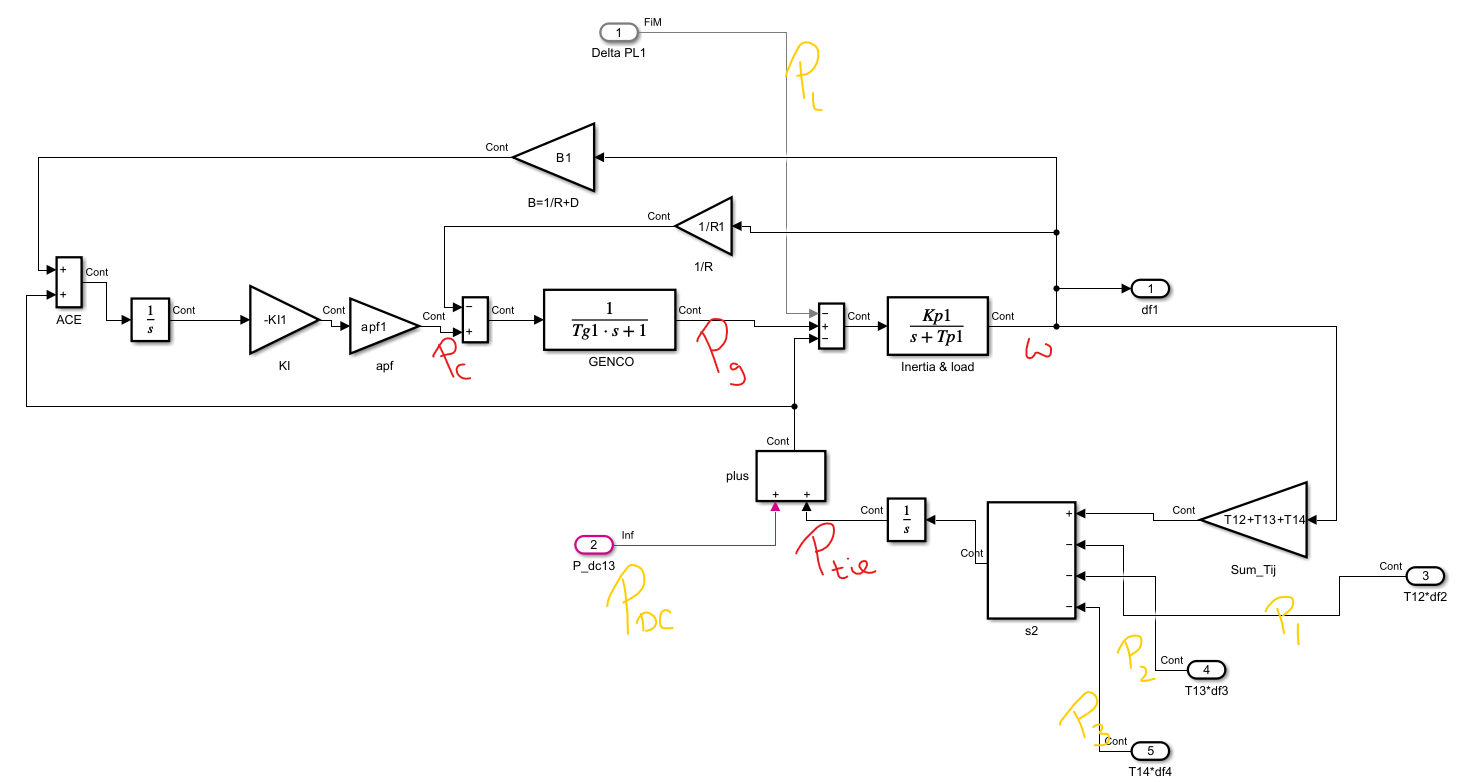

# Parameters

Cconst = 0.15915494327;
Kp = [76; 141.7; 139.6; 114.2]*Cconst/60;
Tp = [14.4; 19.1; 9.39; 9.12];
Tg = 0.38*ones(4,1); 
R = 3/60*ones(4,1); 
Bagc = [0.416; 0.377; 0.378; 0.388]*60;
Kagc = [0.75; 0.25; 0.5; 0.5]*(-0.131);
Kdc = ones(4,1);

T = zeros(4,4);
T(1, 2) = 0.029; 
T(1, 3) = 0.0143; 
T(1, 4) = 0.0099; 
T(2, 3) = 0.0205; 
T(3, 4) = 0.0089;
T = T.*(60/Cconst);
T = T + T';

# State space of system with AGC

% x = [Pc Pg w Ptie]
% u = [Pl Pdc Pi+1 Pi+2 Pi+3]
clear AMatrices BMatrices
AMatrices(4) = struct();
BMatrices(4) = struct();
for i = 1:4
    Amatrix = [
        0, 0, Kagc(i)*Bagc(i), Kagc(i)
        1/Tg(i), -1/Tg(i), -1/Tg(i)/R(i), 0
        0, Kp(i), -Tp(i), -Kp(i)
        0, 0, sum(T(i,:)), 0
    ];
    AMatrices(i).value = Amatrix;
    Bmatrix = [
        0,Kagc(i)*Kdc(i),0,0,0
        0,0,0,0,0
        -Kp(i),-Kp(i)*Kdc(i),0,0,0
        0,0,-T(i, mod(i,4)+1),-T(i, mod(i+1,4)+1),-T(i, mod(i+2,4)+1)
    ];
    BMatrices(i).value = Bmatrix;
end

% x = [Pc Pg w Ptie]1,2,3,4
% u = [Pl Pdc]1,2,3,4
A = [
    AMatrices(1).value, ...
    [zeros(4,2), BMatrices(1).value(:,3), zeros(4,1)], ...
    [zeros(4,2), BMatrices(1).value(:,4), zeros(4,1)], ...
    [zeros(4,2), BMatrices(1).value(:,5), zeros(4,1)]

    [zeros(4,2), BMatrices(2).value(:,3), zeros(4,1)], ...
    AMatrices(2).value, ...
    [zeros(4,2), BMatrices(2).value(:,4), zeros(4,1)], ...
    [zeros(4,2), BMatrices(2).value(:,5), zeros(4,1)]

    [zeros(4,2), BMatrices(3).value(:,3), zeros(4,1)], ...
    [zeros(4,2), BMatrices(3).value(:,4), zeros(4,1)], ...
    AMatrices(3).value, ...
    [zeros(4,2), BMatrices(3).value(:,5), zeros(4,1)]

    [zeros(4,2), BMatrices(4).value(:,3), zeros(4,1)], ...
    [zeros(4,2), BMatrices(4).value(:,4), zeros(4,1)], ...
    [zeros(4,2), BMatrices(4).value(:,5), zeros(4,1)], ...
    AMatrices(4).value
];

B = [
    BMatrices(1).value(:, 1:2), ...
    zeros(4, 6)

    zeros(4,2), ...
    BMatrices(2).value(:, 1:2), ...
    zeros(4,4)

    zeros(4,4), ...
    BMatrices(3).value(:, 1:2), ...
    zeros(4,2)

    zeros(4,6), ...
    BMatrices(4).value(:, 1:2)
];

% eig(A);

# Safety Critical Controller system

The input to this system also include the AGC inputs Pc

% x = [Pg w Ptie]1,2,3,4
% u = [Pc Pl Pdc]1,2,3,4

Ascc = [
    AMatrices(1).value(2:4, 2:4), ...
    [zeros(3,1), BMatrices(1).value(2:4,3), zeros(3,1)], ...
    [zeros(3,1), BMatrices(1).value(2:4,4), zeros(3,1)], ...
    [zeros(3,1), BMatrices(1).value(2:4,5), zeros(3,1)]

    [zeros(3,1), BMatrices(2).value(2:4,3), zeros(3,1)], ...
    AMatrices(2).value(2:4, 2:4), ...
    [zeros(3,1), BMatrices(2).value(2:4,4), zeros(3,1)], ...
    [zeros(3,1), BMatrices(2).value(2:4,5), zeros(3,1)]

    [zeros(3,1), BMatrices(3).value(2:4,3), zeros(3,1)], ...
    [zeros(3,1), BMatrices(3).value(2:4,4), zeros(3,1)], ...
    AMatrices(3).value(2:4, 2:4), ...
    [zeros(3,1), BMatrices(3).value(2:4,5), zeros(3,1)]

    [zeros(3,1), BMatrices(4).value(2:4,3), zeros(3,1)], ...
    [zeros(3,1), BMatrices(4).value(2:4,4), zeros(3,1)], ...
    [zeros(3,1), BMatrices(4).value(2:4,5), zeros(3,1)], ...
    AMatrices(4).value(2:4, 2:4)
];

Bscc = [
    AMatrices(1).value(2:4, 1), ...
    BMatrices(1).value(2:4, 1:2), ...
    zeros(3, 9)

    zeros(3,3), ...
    AMatrices(2).value(2:4, 1), ...
    BMatrices(2).value(2:4, 1:2), ...
    zeros(3,6)

    zeros(3,6), ...
    AMatrices(3).value(2:4, 1), ...
    BMatrices(3).value(2:4, 1:2), ...
    zeros(3,3)

    zeros(3,9), ...
    AMatrices(4).value(2:4, 1), ...
    BMatrices(4).value(2:4, 1:2)
];

ts = 0.1;
C = zeros(4,12);
C(1,2) = 1; C(2,5) = 1; C(3,8) = 1; C(4,11) = 1; % extracting the frequencies
discreteSystem = c2d(ss(Ascc, Bscc, C, zeros(4,12)), ts)


discreteSystem =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12
   x1       0.7404       -2.32     0.03115   -8.65e-05   -0.008177   9.166e-05  -4.985e-05   -0.004984   5.275e-05  -2.859e-05   -0.003511   3.024e-05
   x2     0.008888      0.2097    -0.01045    5.84e-05    0.003799  -6.298e-05   3.506e-05    0.002487   -3.77e-05   2.021e-05     0.00177  -2.172e-05
   x3      0.01185       1.036       0.987    -0.01058      -0.466     0.01167   -0.006664     -0.3342    0.007313   -0.003869     -0.2421    0.004242
   x4   -6.116e-05    -0.01078   6.481e-05      0.7225      -1.898     0.05105  -1.058e-07  -1.614e-05   1.101e-07   -0.000143    -0.01718   0.0001514
   x5     4.13e-05     0.00501  -4.454e-05     0.01355      0.1106    -0.01611   1.135e-07   1.408e-05  -1.191e-07   9.889e-05    0.008327  -0.0001065
   x6    -0.004558     -0.3975    0.005015     0.01809      0.7983 